# Using the Leaderboard Toolbox

Here we are using pre-existing players.csv and scores.csv files. 

type players.csv

Name,ID
Michael Cappello,34524
Andrew Newell,631608
Grzegorz Knor,1861624
Evan,3303717
Yaroslav,3354683
PurpleDiab,5960633
cokakola,7164325
Jakub Mrowka,8171411
Erik Luiten,8960155
Jiahang Li,11433059


player_file = which("players.csv");
players = readtable(player_file,"TextType","string")

## Make the HTML Leaderboard File

f = 'leaderboard.html';
makeLeaderboard(f,players.ID)

## Collect the Data

Run this at a regular interval to get the latest scores.

f = 'scores.csv';
scoreTable = gatherScoreData(f,players.ID)

## Make a Leaderboard Table

t1 = datetime('now')

t1 = datetime
   29-Jun-2022 12:16:30


currentTable = leaderTableAtTime(players, scoreTable, t1)

## Plot Player Scores Over Time

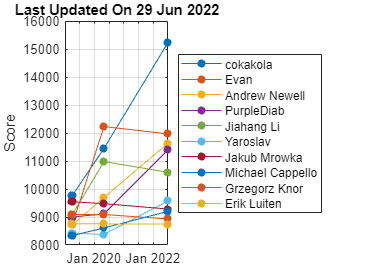

id = currentTable.Id;
clf
hold all
for i = 1:length(id)
    ix = find(scoreTable.Id == id(i));
    plot(scoreTable.Time(ix),scoreTable.Score(ix),'.-', ...
        'MarkerSize',18)
end
hold off
d =  max(scoreTable.Time);
d.Format = "dd MMM uuuu";
ylabel("Score")
ax = gca;
ax.YAxis.Exponent = 0;
title(sprintf('Last Updated On %s',d))
legend(currentTable.Name,'Location',"eastoutside")
box on
grid on

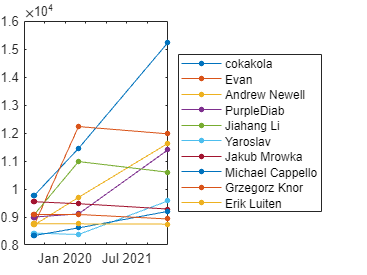

[scoreMatrix,t,playerNames] = makeScoreMatrix(scoreTable, players);

plot(t,scoreMatrix,'.-','MarkerSize',12)
legend(playerNames,"Location","eastoutside")

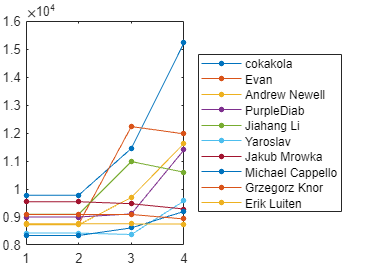

plot(scoreMatrix,'.-','MarkerSize',12)
legend(playerNames,"Location","eastoutside")

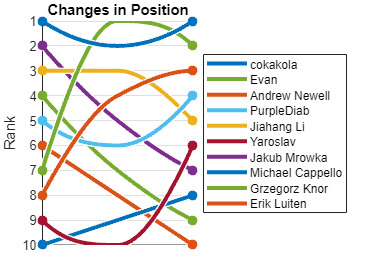

makeRankPlot(scoreMatrix, t, playerNames);

## Changes in the last 30 Days

t2 = datetime;
nDays = 30;
t1 = t2 - days(nDays)

t1 = datetime
   30-May-2022 12:16:34


dMinus30Table = leaderTableAtTime(players,scoreTable,t1);
currentTable = leaderTableAtTime(players,scoreTable,t2);

Rank = zeros(height(players),1);
RankChange = zeros(size(Rank));
ScoreChange = zeros(size(Rank));

for i = 1:height(currentTable)
    Rank(i) = i;
    ixOld = find(dMinus30Table.Id==currentTable.Id(i));
    if isempty(ixOld)
        RankChange(i) = NaN;
        ScoreChange(i) = currentTable.Score(i);
    else
        RankChange(i) = ixOld - Rank(i);
        ScoreChange(i) = currentTable.Score(i) - dMinus30Table.Score(ixOld);
    end
end

currentTable = [currentTable table(Rank,RankChange,ScoreChange)]

fprintf('Changes in the Last %d Days\n\n',nDays);

Changes in the Last 30 Days




for i = 1:height(currentTable)
    if isnan(currentTable.RankChange(i))
        rankStr = "New player this period";
    elseif currentTable.RankChange(i)<0
        rankStr = sprintf("Rank decreased by %d",abs(currentTable.RankChange(i)));
    elseif currentTable.RankChange(i)==0
        rankStr = "Rank unchanged"
    else
        rankStr = sprintf("Rank improved by %d",currentTable.RankChange(i));
    end
    fprintf("%2d. %20s: %4d (%s)\n", ...
        i,currentTable.Name(i), currentTable.Score(i), rankStr);
end

 1.             cokakola: 15225 (Rank improved by 1)
 2.                 Evan: 11970 (Rank decreased by 1)
 3.        Andrew Newell: 11629 (Rank improved by 1)
 4.           PurpleDiab: 11395 (Rank improved by 2)
 5.           Jiahang Li: 10600 (Rank decreased by 2)
 6.             Yaroslav: 9573 (Rank improved by 4)
 7.         Jakub Mrowka: 9285 (Rank decreased by 2)
 8.     Michael Cappello: 9200 (Rank improved by 1)
 9.        Grzegorz Knor: 8930 (Rank decreased by 2)
10.          Erik Luiten: 8745 (Rank decreased by 2)
